# SADEA[1]

[1] Bo. Liu, et, *An Efficient Method for Antenna Design Optimization Based on Evolutionary Computation and Machine Learning Techniques*, IEEE TRANSACTIONS ON ANTENNAS AND PROPAGATION, VOL. 62, NO. 1, JAN 2014.

clc
clear
close all;

#### Step 0: Initialization

% Initialize parameters
x_ub = 10;      % Upper bound for x, denoted as 'a' in the paper
x_lb = -10;     % Lower bound for x, denoted as 'a' in the paper
D = 10;         % Dimensionality, denoted as 'd' in the paper
alpha = 40;     % Initial sample size, denoted as 'α' in the paper. Suggested value: 3*d to 5*d
lambda = 50;    % Population size, denoted as 'λ' in the paper
G_max = 700;    % Maximum number of iterations
F = 0.8;        % Scaling factor
CR = 0.8;       % Crossover rate
tau = 100;      % Number of the τ newest solutions from the database
omega = 2;      % LCB parameter
test_function = @ackley;  % Test function (Ackley Function)

#### Step 1: Use the Latin Hypercube sampling to generate

Use the Latin Hypercube sampling to generate α solutions from [a,b]^d, evaluate all the individuals using exact function evaluations and then use them to form the initial database.

% Generate initial database of solutions
for i = 1:alpha
    % Define the sampling interval's upper and lower bounds
    si_lb = ((x_ub - x_lb) / alpha) * (i - 1) + x_lb; % Upper bound of the sampling interval
    si_ub = (x_ub - x_lb) / alpha * i + x_lb; % Lower bound of the sampling interval

    % Generate a random solution within the sampling interval and record it in the database
    database_x(i, :) = (si_ub - si_lb) * rand(1, D) + si_lb; % Database of recorded solutions
    database_f(i, :) = test_function(database_x(i, :)); % Database of recorded function values
end

#### Step 2: If a preset stopping criterion is met

If a preset stopping criterion is met (e.g., a maximum number of exact function evaluations), output the best solution from the database; otherwise go to step 3.

% Main loop for optimization process
G = 0; % Initialize iteration counter
while G < G_max % Check if maximum number of iterations has been reached
    G = G + 1; % Increment iteration counter by 1

#### Step 3: Select the λ best solutions

Select the best solutions (i.e., with the lowest function values) from the database to form a population. Update the best solution obtained so far.

    % Select the λ(lambda) best individuals from the database
    [f_x_lambda, index_best_x_lambda] = mink(database_f, lambda);
    x_lambda = database_x(index_best_x_lambda, :);

    % Find the best solution and corresponding function value for this generation
    [f_x_best, index_best_x] = min(f_x_lambda);
    x_lambda_best = x_lambda(index_best_x, :);

    % Update the best solution obtained so far
    f_x_best_G(G) = f_x_best;

#### Step 4: DE mutation and crossover operators

Apply the DE mutation (DE/rand/1 or DE/best/1) and crossover (binomial crossover) operators on to generate child solutions.

    % Perform mutation and crossover to generate new solutions
    x = x_lambda; % Select the lambda best individuals as the starting population
    v = mutation(x, x_lambda_best, F, x_ub, x_lb); % Generate a mutation matrix
    u = crossover(x, v, CR); % Generate a crossover matrix

#### Step 5: Take the τ newest solutions and Build GP surrogate model

Take the τ newest solutions from the database (i.e.,the last τ solutions from the database) and their function values as the training data to build a GP surrogate model.

    % Extract the latest τ(tau) solutions and corresponding function values from the database
    train_data = extract_array(database_x, tau);
    function_values = extract_array(database_f, tau);

    % Create options struct based on problem type
    opts = struct();
    opts.type = 'BasicGaussianProcess';
    opts.trainAlgorithm = 'srgplvm';
    opts.generateHyperparameters0 = true;

    % Train the GP model using extracted solutions and function values
    k = oodacefit(train_data, function_values, opts);

#### Step 6: Prescreen the λ child solutions

Prescreen the λ child solutions generated in Step4 by using the GP model from Step5 with the LCB prescreening.

    % Predict the function values of the offspring using the GP model
    [BDACE, MSE] = k.predict(u);

    % Compute the Lower Confidence Bound (LCB) for each offspring
    sigma = sqrt(MSE);
    f_x_LCB = BDACE - omega .* sigma;

#### Step7: Evaluate the prescreened best child solution

Evaluate the prescreened best child solution from Step 6, add this evaluated solution and its function value to the database. Go back to Step2.

    % Find the offspring with the lowest LCB value (i.e., the best offspring)
    [~, index_best_x] = min(f_x_LCB);
    x_LCB_best = u(index_best_x, :); % x_LCB_best represents the position of the optimal solution

    % Evaluate the best offspring using the test function
    f_x_added = test_function(x_LCB_best);

    % Add the best offspring to the database
    database_x = [database_x; x_LCB_best];
    database_f = [database_f; f_x_added];
end % end of while loop



### sqplab_armijo: stop on positive slope


### sqplab_armijo: stop on dxmin

            alpha      = 1.00000e-02
            |d|_inf    = 1.52677e-07
            |xp-x|_inf = 1.52677e-09


### sqplab_armijo: stop on dxmin

            alpha      = 1.00000e-01
            |d|_inf    = 6.41705e-08
            |xp-x|_inf = 6.41705e-09


### sqplab_armijo: stop on dxmin

            alpha      = 1.00000e-01
            |d|_inf    = 3.07900e-08
            |xp-x|_inf = 3.07900e-09


### sqplab_armijo: stop on dxmin

            alpha      = 1.32426e-02
            |d|_inf    = 1.71401e-07
            |xp-x|_inf = 2.26979e-09


### sqplab_armijo: stop on positive slope


### sqplab_armijo: stop on positive slope


### sqplab_armijo: stop on positive slope


### sqplab_armijo: stop on positive slope


### sqplab_armijo: stop on positive slope


### sqplab_armijo: stop on dxmin

            alpha      = 1.00000e-02
            |d|_inf    = 2.54892e-07
            |xp-x|_inf = 2.54892e-09



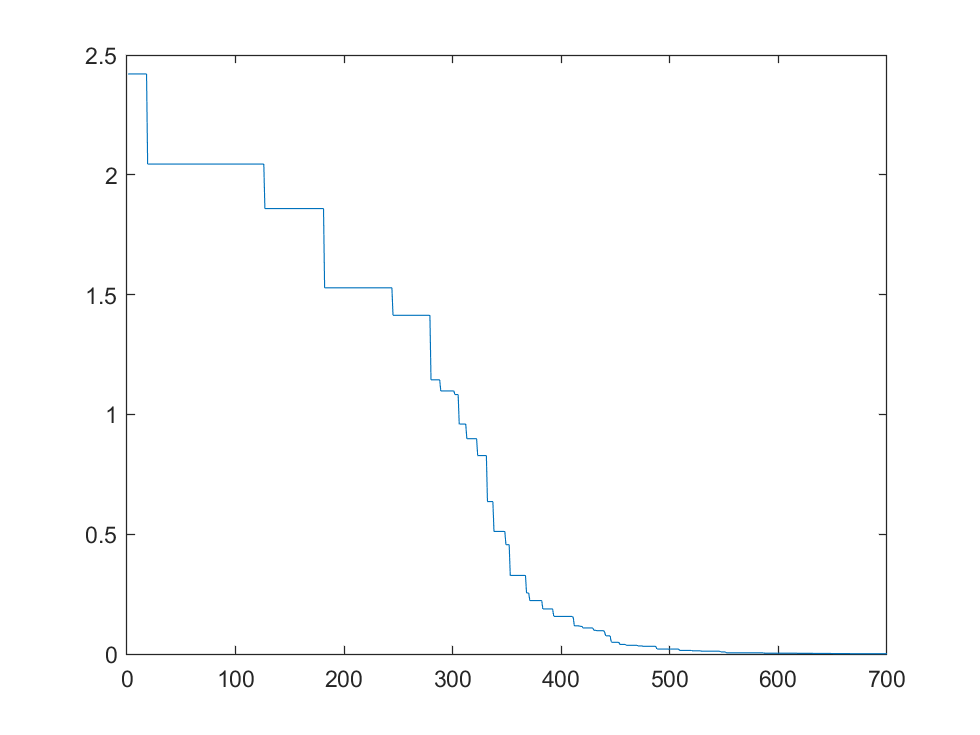

% Find the best solution from the database
[f_x_best, index_best_x] = min(database_f);
x_best = database_x(index_best_x,:);

% Plot the evolution of the best fitness over generations
plot(f_x_best_G);


% Convert the best fitness and location to strings
optValue = num2str(f_x_best);
Location = num2str(x_best);

% Display the optimal value and best location
disp(strcat('The optimal value is', '=', optValue));

The optimal value is=0.0010109


disp(strcat('The best location is', '=', Location));

The best location is=0.00038132  -0.0001357  0.00036831 -7.5968e-06  0.00037682  0.00015525  0.00020303 -0.00034694 -1.5829e-05 -8.3341e-05


#### Function

function output_array = extract_array(input_array, num_rows_to_extract)
% Inputs:
%   input_array - input array
%   num_rows_to_extract - number representing the number of rows to extract
% Outputs:
%   output_array - output array consisting of the rows from num_rows_to_extract to the last row

% Get the number of rows in the input array
num_rows = size(input_array, 1);

% Check if num_rows_to_extract is greater than the number of rows in the input array
% If it is, set num_rows_to_extract equal to the number of rows in the input array
if num_rows_to_extract > num_rows
    num_rows_to_extract = num_rows;
end

% Calculate the rows to extract
start_row = num_rows - num_rows_to_extract + 1;
end_row = num_rows;

% Extract the rows and return them as the output array
output_array = input_array(start_row:end_row, :);
end

function v = mutation(x, x_best, F, x_ub, x_lb)
% The mutation function for differential evolution algorithm.
%
% Inputs:
% x: a matrix of size NP-by-D, where NP is the population size and D is the
% dimension of the problem. It contains the current population.
% x_best: a row vector of size 1-by-D. It contains the best solution found
% so far.
% F: a scalar value. It is a control parameter for differential evolution.
% x_ub: a row vector of size 1-by-D. It contains the upper bounds of the
% problem.
% x_lb: a row vector of size 1-by-D. It contains the lower bounds of the
% problem.
%
% Output:
% v: a matrix of size NP-by-D. It contains the mutated population.

[NP, D] = size(x);
v = zeros(NP, D);

for i = 1:NP
    % Randomly choose 3 different indices in [1, NP]
    r_range = 1:NP;
    r = sort(r_range(randperm(numel(r_range), 3)));
    
    % DE/rand/1 mutation strategy
    % v(i,:) = x(r(1),:) + F*(x(r(2),:) - x(r(3),:));
    
    % DE/best/1 mutation strategy
    v(i,:) = x_best + F*(x(r(1),:) - x(r(2),:));
end

% Ensure the mutated population is within the feasible range
v(v > x_ub) = x_ub;
v(v < x_lb) = x_lb;

end

function u = crossover(x, v, CR)
% The crossover function for differential evolution algorithm.
%
% Inputs:
% x: a matrix of size NP-by-D, where NP is the population size and D is the
% dimension of the problem. It contains the current population.
% v: a matrix of size NP-by-D. It contains the mutated population.
% CR: a scalar value between 0 and 1. It is a control parameter for
% differential evolution.
%
% Output:
% u: a matrix of size NP-by-D. It contains the trial population.

[NP, D] = size(x);
u = zeros(NP, D);

for i = 1:NP
    % Randomly choose a dimension index in [1, D]
    jRand = randi([1, D]);
    for j = 1:D
        k = rand;
        if k <= CR || j == jRand % Ensure at least one element is from v
            u(i, j) = v(i, j);
        else
            u(i, j) = x(i, j);
        end
    end
end

end


